# **Aerial Robotics**

Hello Participants !! 

Welcome to the **Aerial Robotics** Course brought to you by the Aeromodelling Club, IIT Bombay !! 

You must have often wondered how the Micro Air Vehicles are made to exhibit agile and accurate operations autonomously even in highly cluttered environments. So, fasten your seatbelts, and get ready to dive into one of the hottest innovation fields of industry  -  “AERIAL ROBOTICS” !!

This course will take you through an interesting ride over the fascinating basics of aerial robotics in general including the kinematic and dynamic modeling of aerial systems and the design aspects of their control. At the end of this course you will be provided some hardware experience for implementing what you have learned through the course. You will be able to achieve the following learning objectives:

- Understand the basic kinematics of quadcopters

- Understand the domains and requirements of autonomous flights

- Formulate thrust requirements for the drone and size of its propulsion system

- PID for 1-D altitude quadrotor control

- Visualize and deal with Euler Angles and associated Rotation Matrices

- 2-D quadrotor control and controller design

- 3-D quadrotor control and controller design

- Understand the basics of control theory

- Implementation of learnings on a test drone

The course is divided into 5 weeks where you will sequentially achieve the above objectives and implement them on basic problem statements. Every week, in addition to the given tutorials and practice problems, we will have an assignment based on that week’s material which will stimulate your thinking and help you get the most out of this course. These assignments will be sought in MATLAB and will be used for the course evaluation.

The course has been designed on MATLAB LiveScript and Notion. There are embedded links to the tutorials along with the textual explanations of the concepts. You will also get embedded examples at various instances during the course which will be executable in the liveScript simultaneously while learning. For this, we suggest you download MATLAB offline.

## **Week 1**

Welcome to Week 1!

Since the course has been designed on MATLAB and all the embedded tutorials, learning exercises, and assignments will be based on the same, it is important that before diving into the course content, you get familiar with the basics of MATLAB. This is what Week 1 deals with. So, the basic learning outcome for Week 1 is

- Get familiar with MATLAB basics

MATLAB as you may know is a powerful mathematical tool, which is used for a multitude of operations that involves plotting graphs, solving complex equations, formulating functions, controlling commands, and several more. In Aerial Robotics, we widely use MATLAB as an important platform to plot the different graphical characteristics for our systems like the thrust requirement, relative positions, time-dependent configurations which govern the control of the system in various ways. 

Follow the below tutorials one by one and try solving the embedded exercises to get a good command over them. The participants who already have a good understanding of MATLAB can use it as a revision or stay tuned for the upcoming weeks :)

Happy Learning!

## Quadcpter Basics

- [Drone Sizing of Quadcopters](https://drive.google.com/file/d/185ca5gEVjDlNxu7OFk66lBMPK7Qwbj3F/view?usp=sharing)

### **MATLAB Basics**

- [**This reference**](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=gettingstarted&release=R2023b&language=en&) will introduce you to basic MATLAB operations.

- [**This reference**](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=mlbe&release=R2024a&language=en&) will introduce you to the MATLAB environment, its Desktop Features and further operations. 

        You are requested to just go through the above references for a quick headstart ! 

        ( Don't worry, we will brush-up the important ones below! :) ) 

- **Clear All Output**

[Clear Command Window](https://in.mathworks.com/help/matlab/ref/clc.html) (clc)

`clc` clears all the text from the Command Window, resulting in a clear screen. After running `clc`, you cannot use the scroll bar in the Command Window to see previously displayed text. You can, however, use the up-arrow key ↑ in the Command Window to recall statements from the command history.

Use `clc` in a MATLAB® code file to always display output in the same starting position on the screen.

Clear all text from the Command Window before running a command.

- **Create a 3-by-3 matrix of random numbers**

example_variable = rand(3)  

example_variable =     0.3371    0.3112    0.6020
    0.1622    0.5285    0.2630
    0.7943    0.1656    0.6541


- **Clear all text from the Command Window**

clc

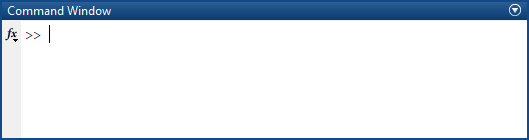

- **Use of clearvars**

[Clear variables from memory](https://in.mathworks.com/help/matlab/ref/clearvars.html)

`clearvars` removes all variables from the currently active workspace.

`clearvars` `dummy_variables` removes the variables specified by `dummy_variables`. If any of the variables are global, `clearvars` removes these variables from the current workspace only, leaving them accessible to any functions that declare them as global.

- [Matlab Variables](https://www.youtube.com/watch?v=L-Y8Q--I2YM)  

Example:

age = 19;
code_name = 47;
CODE_NAME = 48;
age, code_name, CODE_NAME

age = 19

code_name = 47

CODE_NAME = 48

x = 2;
y = (4*(x^2))+(3*x)-7;
y                               % command to print out y

y = 15

% percentage sign is used to comment out a statement. This is an example.

5+(3*6)

ans = 23

- [Creating Vectors](https://www.youtube.com/watch?v=8OQyjKBo0kM)

Example:

x_1 = [-2, 0, 2]; % row vectors made by commas or space
x_2 = [-2; 0; 2]; % column vectors made by semi-colon
x_1, x_2          % command to print out the variables written

x_1 =     -2     0     2


x_2 =     -2
     0
     2


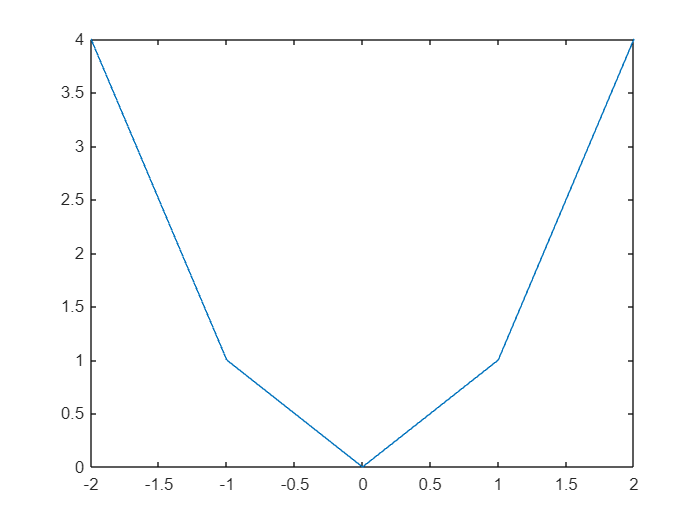

z = [-2, -1, 0, 1, 2];
w = [4, 1, 0, 1, 4];
plot(z, w)            % format is plot(x,y); i.e., here, z will be on x-axis and w on y-axis

- [Using the  :  Operator](https://www.youtube.com/watch?v=-nnyr8jdoFg) 

Example:

% if x = a:b:c ; where a,b,c are numbers, then x is an array of numbers of
% an AP with first term = a, common difference = b, and last term of the AP is the
% highest number of the AP which is <= c ; 
x_3 = -1:0.5:1; 
x_4 = -1:0.3:1;
x_3, x_4

x_3 =    -1.0000   -0.5000         0    0.5000    1.0000


x_4 =    -1.0000   -0.7000   -0.4000   -0.1000    0.2000    0.5000    0.8000


x_5 = -1:1; % here, a = -1, c = 1, (b = 1 by default) ; (a,b,c are as mentioned above)
x_5 

x_5 =     -1     0     1


x_6 = (-1:1)'; % transpose taken
x_6 

x_6 =     -1
     0
     1


-  [Functions](https://www.youtube.com/watch?v=2DZSBODL5oQ)

Example

x_7 = 1;
sin(x_7), log10(x_7), exp(x_7) % standard built-in functions

ans = 0.8415

ans = 0

ans = 2.7183

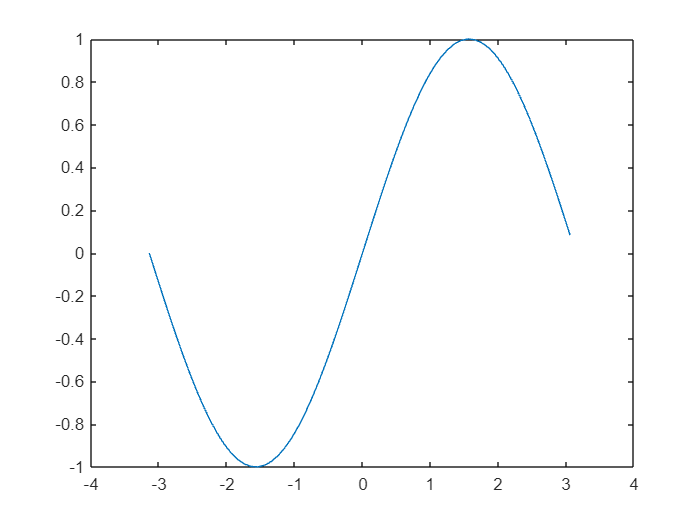

x_8 = -pi:0.1:pi; % pi variable is built-in as pi itself 
y_8 = sin(x_8); % the sin function operates on each element, and y_8 is an array of same size as of x_8 ;
plot(x_8, y_8) 

[a , I] = min([1, 2 ,3 ,4, 5, -5]); % MATLAB follows 1-Based Indexing
% i.e., in above array, index of element 1 is 1, element 4 is 4, and so on
% this format gives the least element of the array, and I gives its index
a , I 

a = -5

I = 6

- **Documentation**

You can always search for matlab documentation of a function, in case you want to know how the function is

used or what is its syntax :- 

doc randn % this opens the official MATLAB documentation of the function randn
% try running it by clicking on 'Run Section' in the 'LIVE EDITOR' panel !

- [Matlab as a calculator](https://www.youtube.com/watch?v=pdPnbSeUQAY)

             Example:

x1 = 5;
3*(x1^2)*((6-x1)^5) 

ans = 75

To solve $y=3x^2 +2x-1$, the solutions are $x=\frac{-b\pm \sqrt{b^2 -4\textrm{ac}}}{2a}$

a =3;
b = 2;
c = -1;
sol1 = (-b+sqrt((b^2)-(4*a*c)))/(2*a)

sol1 = 0.3333

sol2 = (-b-sqrt((b^2)-(4*a*c)))/(2*a)

sol2 = -1

- **Finding Roots of Expressions using *****fsolve *****Function :- **

        To find roots of complex expressions and equations, the *fsolve *function is of utmost use. 

        [This reference](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=rootfinding&release=R2024a&language=en&) will guide you on the syntax of the function and how to use it. 

- [Calculations with vectors](https://www.youtube.com/watch?v=rWoYfSLF3rY)

              Example:

v1 = [1, 2, 3, 4, 5];
v2 = [3, 4, 5, 6, 7];
v1.*v2                    %  the .* and ./ operators perform element-wise operations

ans =      3     8    15    24    35


% thus, they operate only on compatible pairs of arrays/matrices
% below, each element of v1 / corresponding element of v2 is printed
v1./v2

ans =     0.3333    0.5000    0.6000    0.6667    0.7143


v1.^2 % each element of v1 is squared

ans =      1     4     9    16    25


v1+v2 % each element of v1 is added to corresponding element of v2 (compatibility matters !)

ans =      4     6     8    10    12


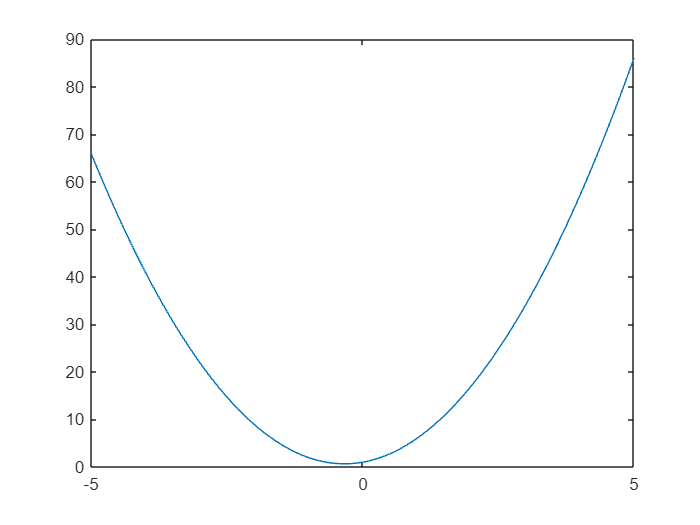


p = -5:0.1:5;
q = 3*(p.^2)+(2*p)+1; % q is an array of same size as of p, and note the .^ operator,
                      % as p is an array. However, there is no need for
                      % 2.*p, as 2 is a scalar
plot(p,q)
hold off;             % 'hold on' command is used between 2 consecutive plot commands, to plot the 2 graphs on the same plot. To make it on separate plots, the 'hold off' command is stated. If nothing stated, the one mentioned latest (hold on OR hold off), would be considered. 

- [Creating Matrices](https://www.youtube.com/watch?v=uEaSPQz5-p0)

Examples

A = [1, 5, 7 ; 8, 0, 4] % similar format (basically ; is used to change the row)

A =      1     5     7
     8     0     4


B = [11, 22, 33;
    44, 55, 66;
    77, 88, 99] 

B =     11    22    33
    44    55    66
    77    88    99


- [Matrix multiplication](https://www.youtube.com/watch?v=ooGBmqU6TVg)

Examples

C = [1, 3, 5;
    2, 4, 6;
    0, 4, 7];
u = [1; 2; 3];
C*u            % between 2 arrays, the * operator performs matrix multiplication (compatibility :) )

ans =     22
    28
    29


- [Logical operators](https://www.youtube.com/watch?v=bnMQZJbOBn8&feature=youtu.be)

Examples

s = 3;                            % this is an assignment, not 'equal to'
v = (s==3) | (s > 5) | (s < -12); % here, 'and'(&) and 'or'(|) are logical operators ;
% if s is 3, or s is greater than 5 or s is less than -12, v is logical 1 ;
v                                 % v is a logical value (True is 1) 

v = logical
   1


1 & 1

ans = logical
   1


1 & 0

ans = logical
   0


1 | 1

ans = logical
   1


1 | 0

ans = logical
   1


0 | 0

ans = logical
   0


- [Conditional data selection](https://www.youtube.com/watch?v=xMfW-RVy4j4&feature=youtu.be)

Examples

e = -2:0.1:2;
E = sin(e);
L = E > 0; % L is a logical array of same size as that of E, such that each element of L depends on whether corresponding element of E is > 0 or not
R = E(L);  % this command creates an array of only those elements of E which are greater than 0 ;
E,R

E =    -0.9093   -0.9463   -0.9738   -0.9917   -0.9996   -0.9975   -0.9854   -0.9636   -0.9320   -0.8912   -0.8415   -0.7833   -0.7174   -0.6442   -0.5646   -0.4794   -0.3894   -0.2955   -0.1987   -0.0998         0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093


R =     0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093


- [FOR loop](https://www.youtube.com/watch?v=3cFv7vnb6KE&feature=youtu.be)

          Example:

var = [1 0 0 0 0 0 0 0] 

var =      1     0     0     0     0     0     0     0


for n = 1:8
    var(n+2) = var(n+1) + var(n); % each element of var (1st and 2nd elements are unchanged) will be such that it is the sum of its previous 2 elements ;
end                               % remember this format; the 'end' keyword is very important ; 
var                               % well, you just created a famous sequence ! ( iykyk ;) )

var =      1     2     3     5     8    13    21    34    55    89


- [If-Else Statement](https://youtu.be/Iauqjo7qAOc)

              Examples:

answer = 'Hi' % string variables enclosed inside ''

answer = 'Hi'

if answer == 'Hi'
    say = 'Hello';
elseif answer  == 'bye'
    say = 'bye';
else 
    say = '';
end
say            % standard format; and variables are case-sensitive ! 

say = 'Hello'

- [Creating Multiple Plots](https://youtu.be/CKHN8xKN-Wk)

              Examples:

% I want to make a lattice of 10 vertical lines, but before that, below are
% some functions we will be using :- 
xy = zeros(5,7)  % ..... this command creates a matrix of all elements = 0, of the given size

xy =      0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0
     0     0     0     0     0     0     0


yx = ones(7,5)   % ..... similarly, the ones function

yx =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


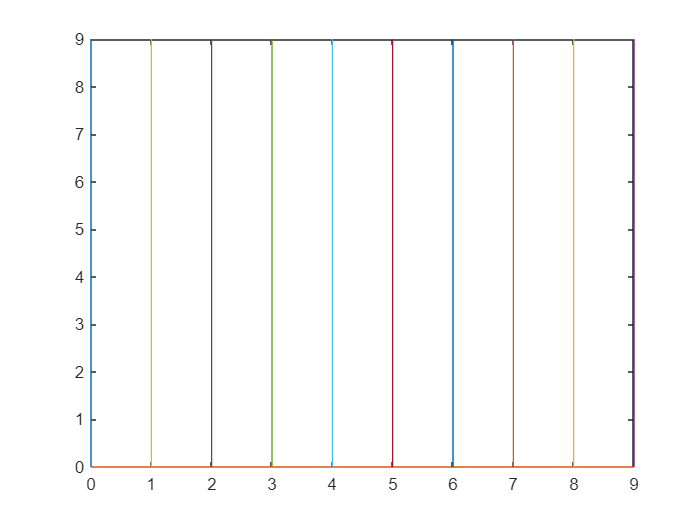

% now, we start making the lattice. The steps are very intuitive, try
% understanding them ! 
clear;
a1 = 0:1:9;
plot(zeros(10, 1),a1);
hold on;
plot(a1, zeros(10, 1));

for n = 1:9

   N = n.* ones(10,1); % to create an array of same elements ; (why?)
   % remember the equations of horizontal and vertical lines ! 
   
   plot(N,a1);
   
end

hold off;

- **Specify Cycling Order of Colors and Line Styles**

              [Indentating and formatting graphs](https://in.mathworks.com/help/matlab/creating_plots/defining-the-color-of-lines-for-plotting.html)

When you use multiple colors and line styles, you can specify whether the plot cycles through all line styles before, after, or at the same time as the colors by setting the [`LineStyleCyclingMethod`](https://in.mathworks.com/help/matlab/ref/matlab.graphics.axis.axes-properties.html#budumk7_sep_mw_51272a7a-f227-49cf-bbe6-b719bc99f1aa) property. This property can have one of three values:

- `"aftercolor"` — Cycle through the line styles after the colors. This value is the default.

- `"beforecolor"` — Cycle through the line styles before the colors.

- `"withcolor"` — Cycle through the line styles with the colors.

Q. Plot four lines. Set the `LineStyleOrder` property to three line styles, and set the `ColorOrder` property to three colors by passing an array of three hexadecimal color codes to the `colororder` function. Then add a legend.

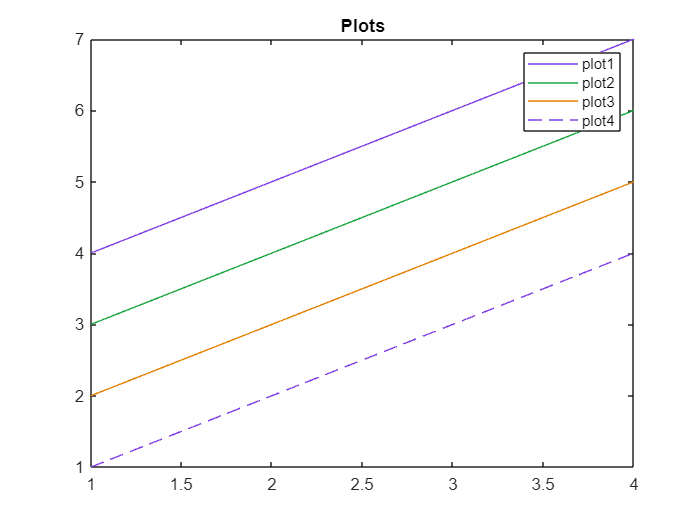

% Plot four lines
plot([4 5 6 7])
hold on
plot([3 4 5 6])
plot([2 3 4 5])
plot([1 2 3 4])
hold off

% Set the line style order and color order
ax = gca; % creates axes; run 'doc ax' in a fresh section for syntax info ;  
ax.LineStyleOrder = ["-"; "--"; "-o"];
colororder(["#8040E6";"#1AA640";"#E68000"])
title("Plots")
legend("plot1","plot2","plot3","plot4") % legends added in order ; 

The above plot contains four lines with three colors and two line styles. The first three lines are solid with unique colors. The last line is dashed and the has the same color as the first solid line. The plot also has a title and a legend.

[Click here to know about the different Line Properties in MATLAB](https://in.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html)

By default, the plot cycles through all the colors with the first (solid) line style before it displays the next (dashed) line style. Because there are three colours, only two of the line styles are used in the four-line plot.

- [Annotating the plots](https://youtu.be/0tQ_QKLgPqY)

             The short video above explains annotations in MATLAB clearly. 

- [Solving System of Linear Equations](https://youtu.be/UQk6HnuAtyc)

              As learnt in Linear Algebra, the system is represented in the form of Ax = b; where A and b are known, and

              x is to be found. 

              Example:

A = [-27 6 3; 10 -3 -5; -4 -3 2]

A =    -27     6     3
    10    -3    -5
    -4    -3     2


b = [-105; -63; 42]

b =   -105
   -63
    42


x = A\b % the backslash (\) directly solves the system Ax = b !!

x =     6.0000
   -4.0000
   27.0000


If A is singular ( det(A) = 0 ) ,  then MATLAB will tell you ( probably an error message would be shown ). 

If a linear system is underdetermined and has an infinite number of solutions, the backslash operator returns the solution with the most zero elements. If a system is overdetermined and has no solution, the backslash operator returns the "best" vector by minimizing the squares of the error (least squares fitting). 

( MA106/MA110 vibes :) ) 

- **EigenValue Decomposition**

When you multiply a matrix and its eigenvector, the eigenvector is simply scaled, and the scaling factor is the eigenvalue.

A = [-27 6 3; 10 -3 -5; -4 -3 2] ; 
[V,D] = eig(A) % this is the eig function ; 

V =     0.9350   -0.0365    0.2682
   -0.3438   -0.5932    0.7484
    0.0876    0.8042    0.6066


D =   -28.9249         0         0
         0    4.3944         0
         0         0   -3.4695


% A is the matrix for which to find the eigenvalue decomposition.
% V is the matrix whose columns are the eigenvectors of A. The eigenvectors are normalized to have magnitude 1.
% D is the diagonal matrix whose diagonal elements are the eigenvalues of A.
% For each eigenvector in V, its corresponding eigenvalue can be found in the same column of the matrix D.

- [Symbolic Math in MATLAB](https://youtu.be/kNqtsuHBADM)

              Suppose you want to plot a 3-D graph.

              Examples:

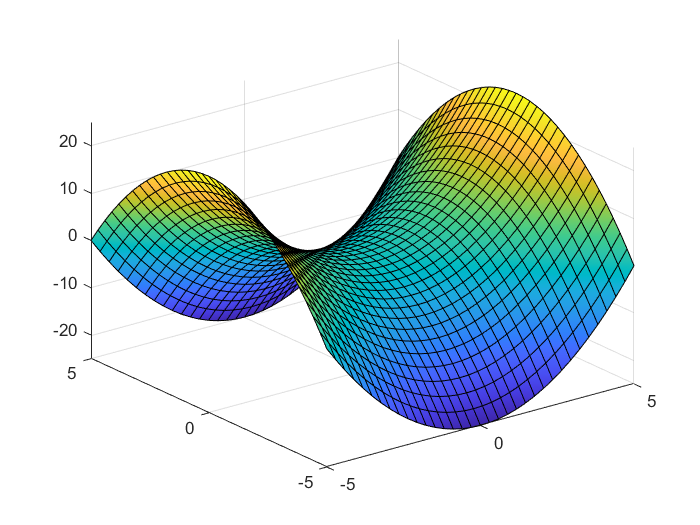

syms x y z        % syntax for activating use of symbolic math
z(x,y) = x^2-y^2; % definition of function to be plotted
fsurf(z)          % command for plotting z as a function of x and y

% Now let's have a look at the solution of z = 0 for the above curve
solve(z == 0 , x) % remember this syntax

$$ans = \left(\begin{array}{c} y\\ -y \end{array}\right)$$

- [Function as an Input](https://youtu.be/MhPf5uP3tzs)

             Example:

% Now we can try and find how x^4-y^2 looks like just by using the result
% obtained in previous cells
f = @(l)l^2; % syntax for defining f = l^2
a = z(f,y)   % z(l^2,y) = (l^2)^2 - y^2 ; 

$$a = l^{4}-y^{2}$$

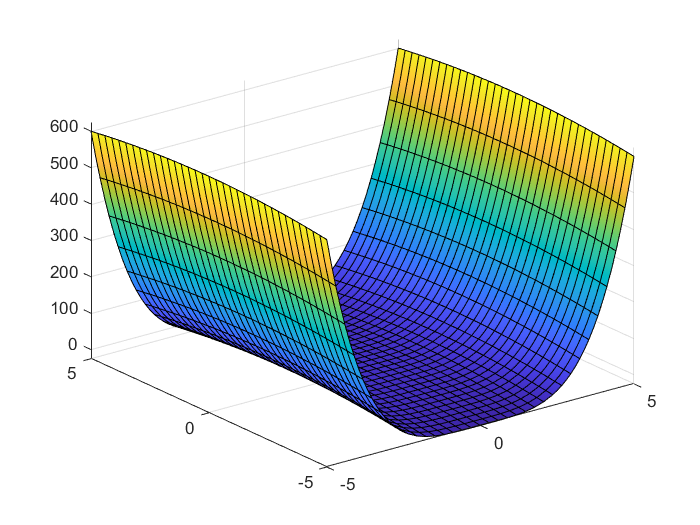

fsurf(a)     % plotting a ; 

You can view the [MATLAB Plot Gallery](https://in.mathworks.com/products/matlab/plot-gallery.html) for various kinds of plots and graphs offered in MATLAB.   

- [ODE45](https://youtu.be/GyGCn7Z4Xqg)

             MATLAB solves differential equations with a numerical algorithm, and ode45 is one such solver which we

             use frequently. 

             Examples:

% The easiest example is the decay equation, like dN/dt = -5*N ; 
% follow the syntax given :- 
dNdt = @(t,N)-5*N ; % function handle defined;
tspan = [0,5] ;     % range of t defined, over which the eq. is to be solved; 
N0 = 10 ;           % initial value of N defined; 
dNdt

dNdt = function_handle with value:
    @(t,N)-5*N


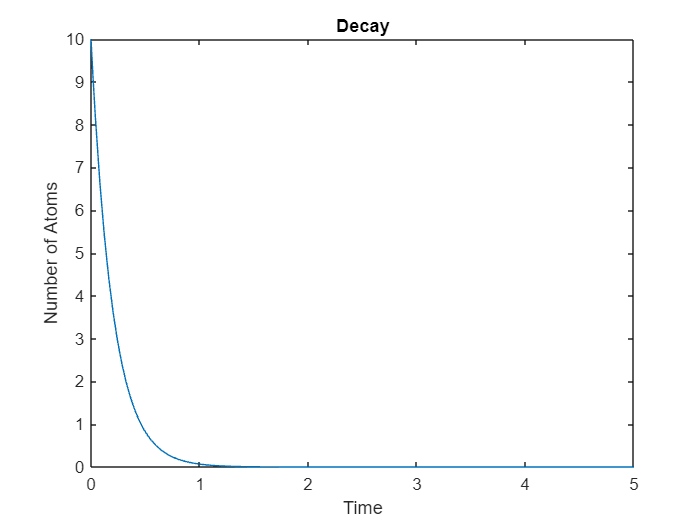

[tsol,Nsol] = ode45(dNdt,tspan,N0); % syntax for ode45 usage; 
plot(tsol,Nsol) ; title("Decay") ; xlabel("Time") ; ylabel("Number of Atoms") ; % plotting the solution obtained; 

- [Higher Order ODEs](https://youtu.be/fumznzFLjK8)

             Examples:

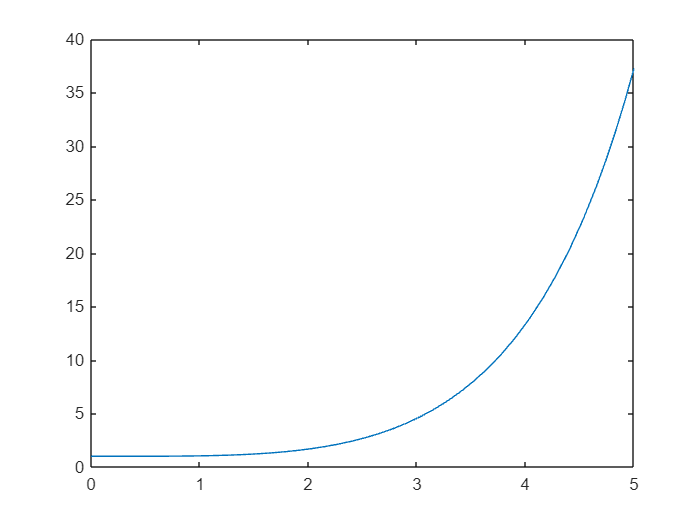

% For this let's use the fourth order equation : d4y/dx4 = y
% the idea is to use multible variables, reducing the equation to many ..
% .. simultaneous 1st order equations, then solving them in a similar way ; as shown in the video above ;  
dydx = @(x,y)[y(2);y(3);y(4);y(1)] ; % y=[y(1);y(2);y(3);y(4)] ; by default, where y(2)=dy(1)/dx, and so on ; 
% y(1) is y, y(2) is dy/dx, y(3) is d2y/dx2, and y(4) is d3y/dx3 ; and we have to define d4y/dx4 = y ( d(y(4))/dx = y(1) ) ;  
x = [0,5];      % this is a row vector
y0 = [1;0;0;0]; % this is a column vector of the initial values of all variables defined ; order and syntax matters ! 
[xsol,ysol] = ode45(dydx,x,y0);
plot(xsol,ysol(:,1))  % plotting only y vs x, and thus, we are ignoring the derivatives of y for plotting purposes ;    

You can refer to [this link](https://matlabacademy.mathworks.com/artifacts/quick-reference.html?course=odes&release=R2024a&language=en&) for further knowledge on ODEs in MATLAB. 

**For futher reference or recap, **[**click here.**](https://www.youtube.com/watch?v=7f50sQYjNRA)

[**Reference List for Functions in MATLAB**](https://in.mathworks.com/help/matlab/referencelist.html?type=function&s_tid=CRUX_topnav)

**Assignment:**

**Sherlock Holmes and Dr. Watson are on the run to catch you. You have challenged Watson and Sherlock to catch you amidst the maze. They are stuck in the maze set by you and they have to solve clues with the help of each other and tackle you at a point.    **

If the point at which Dr. Watson and Sherlock meet, is on your trajectory, then the protagonists can team up and take you down, i.e.,** the protagonists win. **

If their paths don't have a common point of intersection, then you outsmart them individually and escape successfully, i.e.,** the protagonists lose.**

**The given set of equations describe the path they transverse in the maze :**

**y^{2} = x^{3}+x+1        (Sherlock)**

**y^{2}/9 + x^{2}/16 = 1  (Dr. Watson)**

**y = 4-x^{2}                    (You)**

- **Find out who wins?**

- **If the protagonists win then find out the point at which they catch you.**

- **If you win then find out the point at which you outsmart the two -  1) Sherlock  and  2) Dr.Watson**

You can write your code here :-    